# ***Wireless Communications***

## ***CA1***

### ***Section 2***

### ***Part 1 - الف***

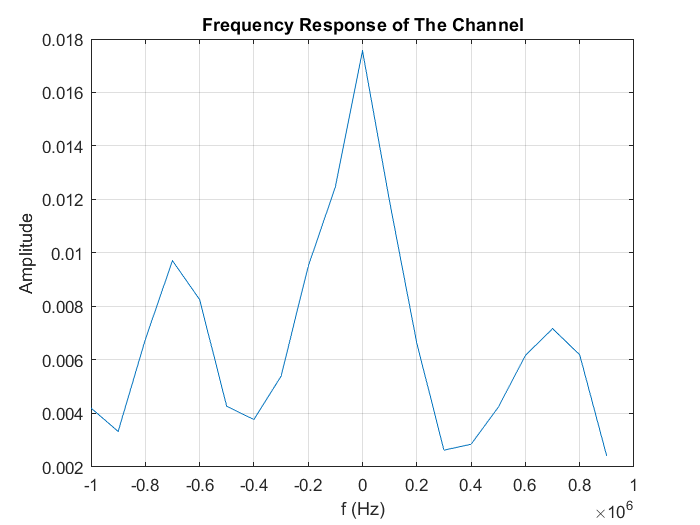

N = 15;
tau1 = 1e-6;       % Micro Second
tau2 = 10e-6;      % Micro Second
fh = 1e6;
fs = 2*fh;
Tm = tau2;
N_h = Tm * fs;
tau = tau1 + (tau2-tau1) * rand(N,1);
tau = sort(tau);
phi = pi/2 * rand(N,1);
sigma = sqrt(1e-3*0.5*((tau).^-4));
alpha = raylrnd(sigma);
h = zeros(N_h,1);
indecies = ceil(tau*fs);
for i=1:N
    idx = indecies(i);
    h(idx) = h(idx) + alpha(i)*exp(-1i*phi(i));
end
h = h * 1e-12;
f = -fh:fs/N_h:fh-fs/N_h;
H = fftshift(fft(h));
figure(1);
plot(f,abs(H));
xlabel("f (Hz)");
ylabel("Amplitude");
grid on;
title("Frequency Response of The Channel");

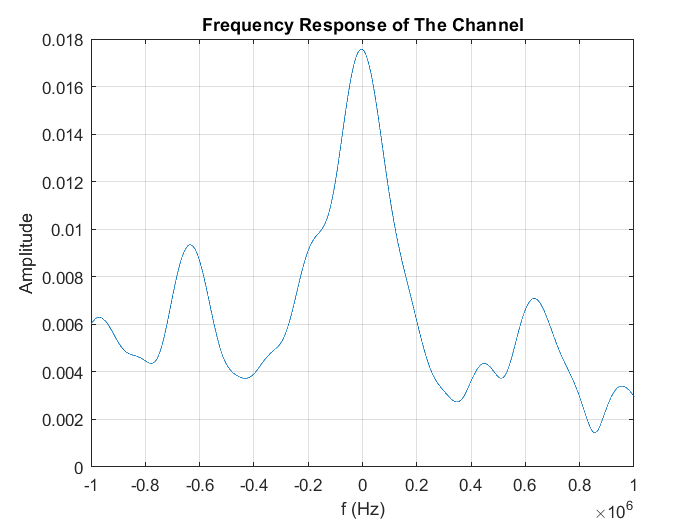

f = -fh:fh-1;
H = zeros(length(f),1);
for i=1:length(f)
    for j=1:N
        H(i) = H(i) + alpha(j)*exp(-1i*phi(j))*exp(-1i*2*pi*f(i)*tau(j));
    end
end
H = H * 1e-12;
figure(2);
plot(f,abs(H));
xlabel("f (Hz)");
ylabel("Amplitude");
grid on;
title("Frequency Response of The Channel");

### ***Part 2 - ب***

fc = 3e9;
t = 0.2;
c = 3e8;
v = 30;
lambda = c/fc;
N_exp = 1e5;
h_vals = zeros(N_exp,1);
for i=1:N_exp
    tau = tau1 + (tau2-tau1) * rand(N,1);
    tau = sort(tau);
    phi = pi/2 * rand(N,1);
    sigma = sqrt(1e-3*0.5*((tau).^-4));
    alpha = raylrnd(sigma);
    fd = v/lambda * cos(pi/2 * rand());
    h = sum(alpha .* exp(1i*phi));
    h = h * exp(1i*2*pi*fd*t);
    h_abs = abs(h);
    h_vals(i) = h_abs;
end
h_vals = h_vals * 1e-12;

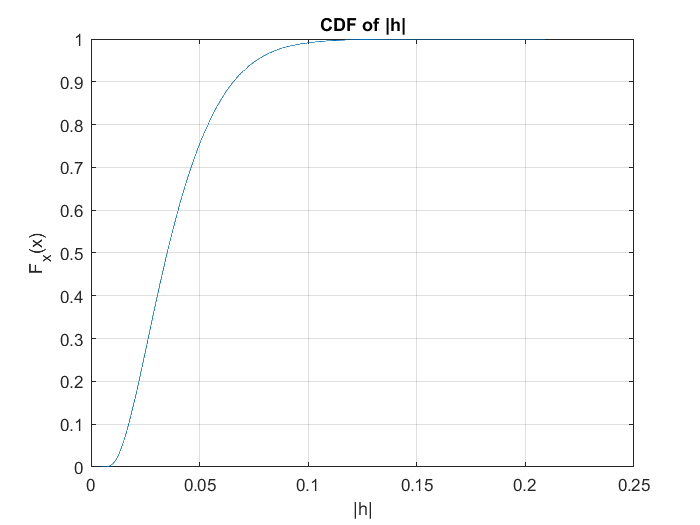

E_h = mean(h_vals);
cdfplot(h_vals);
xlabel('|h|');
ylabel('F_x(x)');
title("CDF of |h|");
grid on;

disp("Expectation of |h|^2 :")

Expectation of |h|^2 :


disp(E_h)

    0.0389

